## **脉冲波形传输 **

### **参数设置**

clearvars;
close all;
clc;
rng(2023);  %固定随机种子，保证结果可复现

% 波形参数
V = 2; % 幅度
T = 1:1:10; % 持续时间
% 相关波形的增益
alpha = 3;
% 噪声的单边功率谱密度
n0 = 2;
% 采样时间间隔
delta_t = [0.1; 0.01];
% 重复实验次数，可修改
N = 1e5;
% 符号均方为Ex2,符号集合为{-1，1}，等概选取
Ex2 = 1;
% 理论信号波形能量
Es = V^2.*T;


%%下面几个矩阵都是2×10矩阵，对应两个△t和十个T的值
% 判决符号的理论噪声均方
noise_energy_theory = zeros(length(delta_t),length(T));
% 判决符号的理论信号均方
signal_energy_theory = zeros(length(delta_t),length(T));
% 判决符号的统计噪声均方
noise_energy = zeros(length(delta_t),length(T));
% 判决符号的统计信号均方
signal_energy = zeros(length(delta_t),length(T));
% 误符号率
ser = zeros(length(delta_t),length(T));

### 具体计算

for cnt1 = 1:length(delta_t)        %对delta_t遍历
    for cnt2 = 1:length(T)          %对T遍历
        t = (0:floor( T(cnt2) / delta_t(cnt1) )-1)'*delta_t(cnt1);
        % 成形脉冲
        p_t = V * ones(size(t));            %p(t)是成形脉冲
        g_t = alpha * p_t;                  %g(t)是接收端相关波形
        noise_energy_theory(cnt1,cnt2) = n0/2*sum(g_t.*g_t)*delta_t(cnt1);      %理论噪声能量
        signal_energy_theory(cnt1,cnt2) = Ex2*(sum(p_t.*g_t)*delta_t(cnt1))^2;  %理论信号能量
        for cnt3 = 1:N      %每个cnt3值代表一次传输
            % 随机生成一个传输符号{-1，1}
            x = randi([0,1],1)*2-1;
            % 生成一个符号的波形采样序列
            x_t = x.*p_t;
            % 加性噪声
            noise_power = n0/2/delta_t(cnt1);           %噪声功率     
            noise = normrnd(0,sqrt(noise_power),size(t)) ;    %噪声分布
            % AWGN信道
            y_t = x_t + noise;
            % 相关接收
            y = sum(y_t.*g_t)*delta_t(cnt1);
            % 判决结果
            x_hat = 1-2*(y<=0);
            % 累计误符号率
            ser(cnt1,cnt2) =ser(cnt1,cnt2)+ double(x~=x_hat);
            % 累计噪声能量
            noise_energy(cnt1,cnt2) = noise_energy(cnt1,cnt2) + (sum(g_t.*noise)*delta_t(cnt1))^2;
            % 累计符号能量
            signal_energy(cnt1,cnt2) = signal_energy(cnt1,cnt2) + (sum(g_t.*x_t)*delta_t(cnt1))^2;
        end
    end
end

ser = ser/N;
noise_energy = noise_energy/N;
signal_energy = signal_energy/N;
% 判决符号统计信噪比
snr_dB = 10*log10(signal_energy./noise_energy);
% 判决符号理论信噪比
snr_dB_theory = 10*log10(signal_energy_theory./noise_energy_theory);

% 计算波形的理论信噪比Es = V^2*T
Es_n0_wave = V^2*T/n0;
Es_n0_wave_dB = 10*log10(Es_n0_wave);

ser_theory = qfunc(sqrt(2*Es_n0_wave));

### 绘图

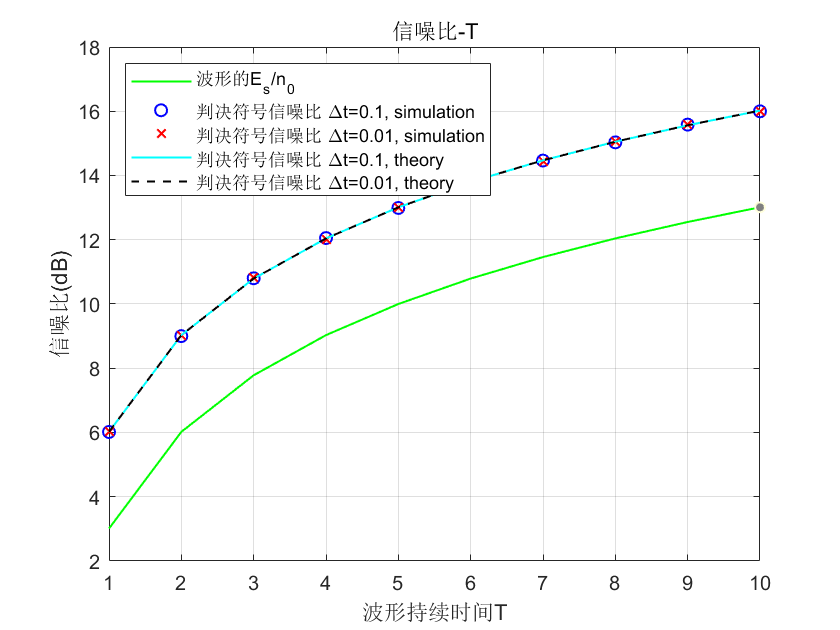

% 绘图
figure;
plot(T, Es_n0_wave_dB, 'g', ...
    T, snr_dB(1,:), 'bo', ...
    T, snr_dB(2,:), 'rx', ...
    T, snr_dB_theory(1,:), 'c-', ...
    T, snr_dB_theory(2,:), 'k--', ...
    'LineWidth', 1);
xlabel('波形持续时间T');
ylabel('信噪比(dB)');
legend('波形的E_s/n_0', ...
    '判决符号信噪比 \Deltat=0.1, simulation', ...
    '判决符号信噪比 \Deltat=0.01, simulation', ...
    '判决符号信噪比 \Deltat=0.1, theory', ...
    '判决符号信噪比 \Deltat=0.01, theory', ...
    'Location', 'northwest');
title('信噪比-T');
box on;
grid on;

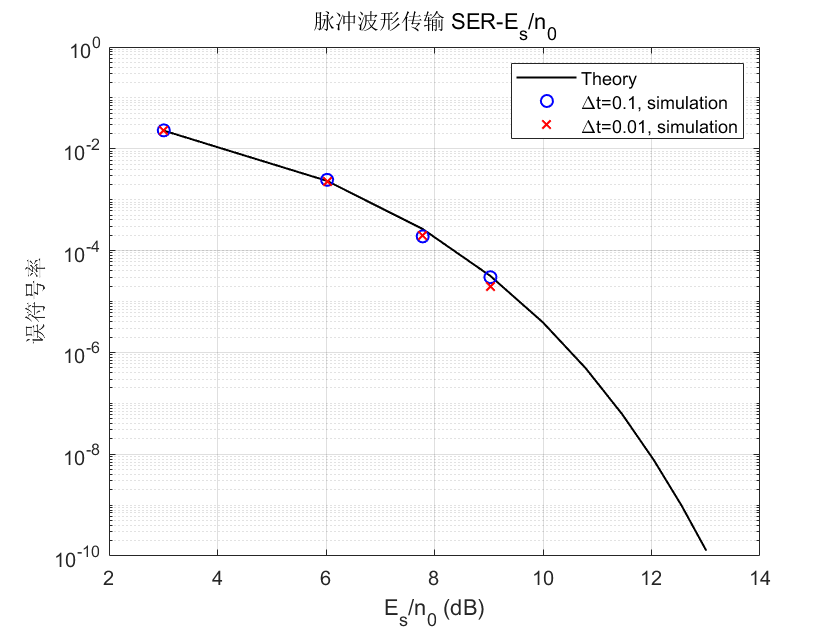




figure;
semilogy(Es_n0_wave_dB, ser_theory, 'k', ...
    Es_n0_wave_dB, ser(1,:), 'bo', ...
    Es_n0_wave_dB, ser(2,:), 'rx', ...
    'LineWidth', 1);
xlabel('E_s/n_0 (dB)');
ylabel('误符号率');
legend('Theory', ...
    '\Deltat=0.1, simulation', ...
    '\Deltat=0.01, simulation');
title('脉冲波形传输 SER-E_s/n_0');
box on;
grid on;